# Week 3 QUIZ 1

#### Question 1

To complete this quiz, you need to import the flights data for January 2015 using the provided import function.

`1`

- `flights = importFlightsData("flightsJan.csv");`

How many variables in the flights table have at least one missing entry?

flights = importFlightsData("flightsJan.csv")

flights = 469968×20 table
         AIRLINE         TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    _________________    ___________    _____________    ______    ___________    ________________________    _____________________    ____________


summary(flights); %10

Variables:

    AIRLINE: 469968×1 categorical

        Values:

            American Airlines                   44059
            Alaska Airlines                     13257
            JetBlue Airways                     21623
            Delta Airlines                      64421
            Atlantic Southeast Airlines         49925
            Frontier Airlines                    6829
            Hawaiian Airlines                    6440
            American Eagle Airlines             29900
            Spirit Airlines                      8743
            Skywest Airlines                    48114
            United Airlines                     38395
            US Airways                          33489
            Virgin America                       4731
            Southwest Airlines             1.0004e+05

    TAIL_NUMBER: 469968×1 categorical

        Values:

            N001AA            61  
            N002AA            59  
            N003AA 

#### Question 2

You can verify that CANCELLATION_CODE is missing whenever CANCELLED = 0, and that ACTUAL_ARRIVAL_TIME is missing whenever CANCELLED = 1. 

What mechanism describes the missing entries in CANCELLATION_CODE and ACTUAL_ARRIVAL_TIME? 

- Missing at Random (MAR)

- Missing Completely at Random (MCAR)

- Missing not at Random (MNAR)

- Need more information

MAR

#### Question 3

The next questions investigate if there is a correlation between diverted and cancelled flights. The figure below shows the number of diverted and cancelled flights for each hour (top two plots). The bottom two plots were created using the "Smooth Data" live task using a moving mean with a centered window of 7 days.

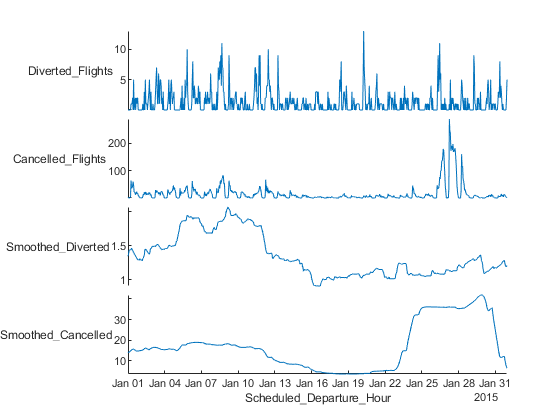

It looks like the smoothed diversions and cancellations may trend together up until the later part of the month. The original cancellations data appears to have significant outliers late in the month, which have a significant impact on the smoothing results. Which of the following approaches would reduce the effect caused by the outliers? (Select all correct answers.) 

- Before smoothing, remove the outliers from the cancelled data and the corresponding points from the diverted data

- Reduce the window size when smoothing

- Before smoothing, normalize the cancellations data. 

- Change the smoothing method to be a moving median rather than a moving mean.

#### Question 4

Use the code below to create a table with the total flights, diverted flights, and cancelled flights each hour over the month. 

- `flights.SCHEDULED_DEPARTURE_HOUR`` = dateshift(flights.``SCHEDULED_DEPARTURE_TIME``,"start","hour");`

- `flightsNotArriving = groupsummary(flights,"SCHEDULED_DEPARTURE_HOUR``","sum",["``DIVERTED``" , "``CANCELLED``"]);`

- `flightsNotArriving.Properties``.``VariableNames`` = [ "``Scheduled_Departure_Hour``" "``Total_Flights``" "``Diverted_Flights``" "``Cancelled_Flights``"]; `

This table contains the data in the first two plots in Question 3. 

Remove the outliers in the cancelled flights using the "quartiles" method with the default threshold factor. Make sure the corresponding points are also removed from the diverted and scheduled time. 

How many outliers are removed? 

flights.SCHEDULED_DEPARTURE_HOUR = dateshift(flights.SCHEDULED_DEPARTURE_TIME,"start","hour");

flightsNotArriving = 725×4 table
    Scheduled_Departure_Hour    Total_Flights    Diverted_Flights    Cancelled_Flights
    ________________________    _____________    ________________    _________________

      01-Jan-2015 00:00:00            21                0                    0        
      01-Jan-2015 01:00:00            21                0                    1        
      01-Jan-2015 02:00:00             8                0                    1        
      01-Jan-2015 03:00:00             2                0                    0        
      01-Jan-2015 04:00:00             4                0                    0        
      01-Jan-2015 05:00:00           116                0                    7        
      01-Jan-2015 06:00:00           658                1                   64        
      01-Jan-2015 07:00:00           722       

flightsNotArriving = groupsummary(flights,"SCHEDULED_DEPARTURE_HOUR","sum",["DIVERTED" , "CANCELLED"]);
flightsNotArriving.Properties.VariableNames = [ "Scheduled_Departure_Hour" "Total_Flights" "Diverted_Flights" "Cancelled_Flights"]

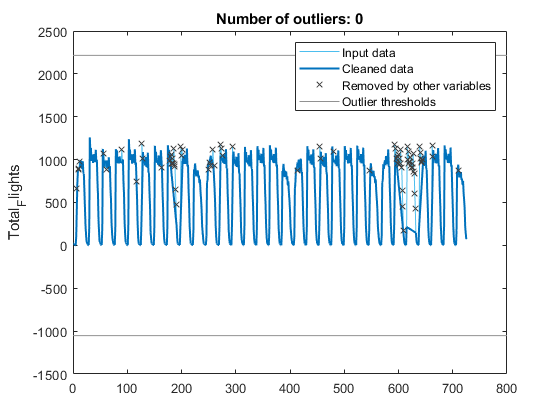

% Remove outliers
[newTable,outlierIndices] = rmoutliers(flightsNotArriving,"quartiles",...
    "DataVariables",["Total_Flights","Diverted_Flights","Cancelled_Flights"]);

% Display results
clf
plot(flightsNotArriving.Total_Flights,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(find(~outlierIndices),newTable.Total_Flights,"Color",[0 114 189]/255,...
    "LineWidth",1.5,"DisplayName","Cleaned data")

% Additional outlier computations for plot
[outliersForPlot,thresholdLow,thresholdHigh] = ...
    isoutlier(flightsNotArriving.Total_Flights,"quartiles");

% Plot outliers
plot(find(outliersForPlot),flightsNotArriving.Total_Flights(outliersForPlot),...
    "x","Color",[217 83 25]/255,"DisplayName","Outliers")
title("Number of outliers: " + nnz(outliersForPlot))

% Plot data in rows where other variables contain outliers
mask = outlierIndices & ~outliersForPlot;
plot(find(mask),flightsNotArriving.Total_Flights(mask),"x",...
    "Color",[64 64 64]/255,"DisplayName","Removed by other variables")

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
legend
ylabel("Total_Flights")

clear outliersForPlot thresholdLow thresholdHigh mask

#### Question 5

Using the results from the previous question (Diverted_Flights and Cancelled_Flights with outliers removed) apply a moving mean smoothing with a centered window of 7 days.  

If you visualize the outcome, you should see the following.

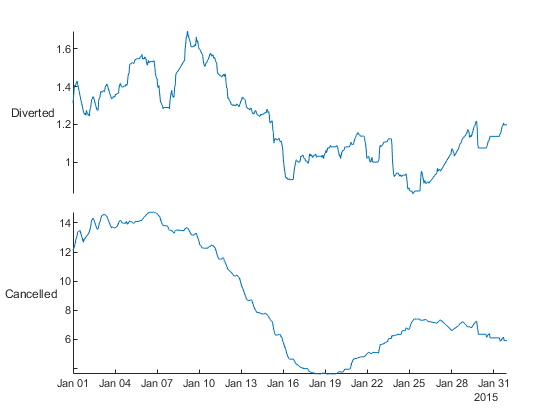

There appears to be a stronger correlation. What is the correlation coefficient for cancelled and diverted flights?

- 0.20

- 0.91

- 0.83

- 0.75

- 0.06

#### Question 6

Below, the previous smoothed results have been normalized using four different normalization methods.

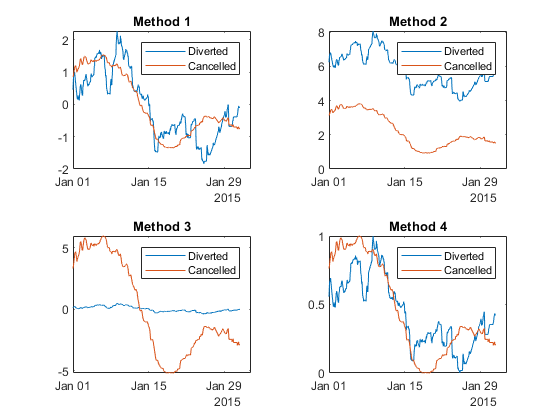

Examine the plots closely and/or try each method to see the results. For example:`1`

- `normalize(dataToNomalize, "scale")`

In order from 1 to 4, which normalization method was used?

- center , scale , range , zscore

- zscore , scale , center, range

- zscore , range , scale , center

- scale , range , center , zscore


zscore , scale , center, range

Unrecognized function or variable 'dataToNomalize'.